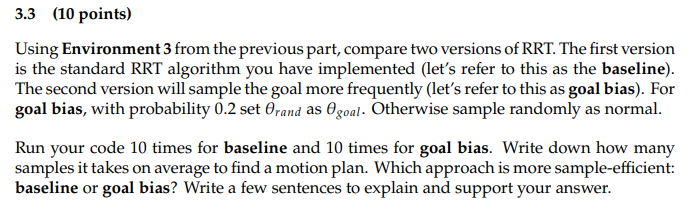

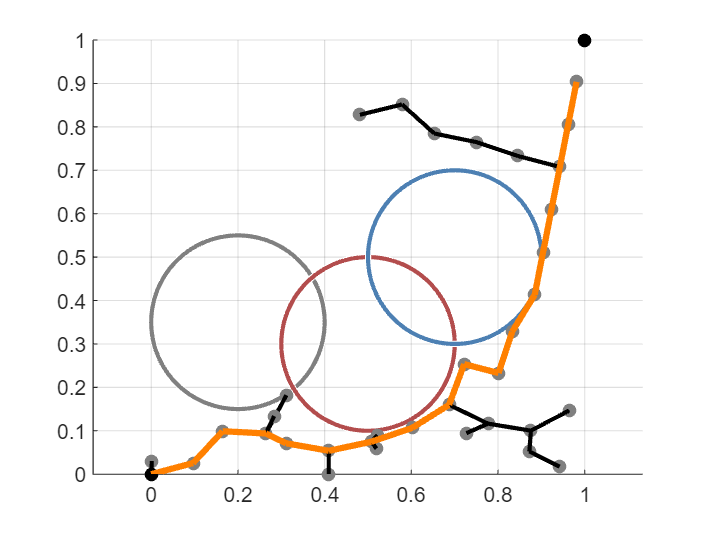

% Goal Bias

clear
close all
% Environment initiation
theta_start.coord = [0; 0];
theta_goal = [1; 1];

% Obstacle Parameters
% First obstacle center and radius
center = [0.2; 0.35];
radius = 0.2;
% Second obstacle center and radius
center2 = [0.5; 0.3]; 
radius2 = 0.2;
% Third obstacle center and radius
center3 = [0.7; 0.5];
radius3 = 0.2;

% Specifying parameters
epsilon = 0.1;
delta = 0.1;
N = 1000;

% Visualizing the environment
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
viscircles(center', radius, 'Color', [0.5, 0.5, 0.5]);
viscircles(center2', radius2, 'Color', [0.7, 0.3, 0.3]); % Visualizing the second obstacle
viscircles(center3', radius3, 'Color', [0.3, 0.5, 0.7]); % Visualizing the third obstacle
plot(0, 0, 'ko', 'MarkerFaceColor', 'k')
plot(1, 1, 'ko', 'MarkerFaceColor', 'k')

% Initializing the tree
theta_start.parent = 0;
G(1) = theta_start;

for idx = 1:N
    
    % Stop if the last node in G is close to theta_goal
    if norm(G(end).coord  - theta_goal) < epsilon
        break
    end

    % sample random joint position: probability 0.2
    
    if rand() < 0.2
        theta_rand = theta_goal;
    else
        theta_rand = rand(2,1);
    end
    
    % find node in G nearest to theta_rand
    min_dist = inf;
    theta_near_index = 0;

    for jdx = 1:length(G)
        coord = G(jdx).coord;
        dist = norm(theta_rand - coord);
        if dist < min_dist
            min_dist = dist;
            theta_near_index = jdx;
        end
    end

    theta_near = G(theta_near_index);
    % take a step from theta_near towards theta_rand
    vec_to_rand = theta_rand - theta_near.coord;
    dist_to_rand = norm(vec_to_rand);
    if dist_to_rand < delta
        theta_new.coord = theta_rand;
    else
        theta_new.coord = theta_near.coord + delta * ...
        vec_to_rand/dist_to_rand;
    end
    
    % check if theta_new is collision free with all obstacles
    dist_to_obs1 = norm(theta_new.coord - center);
    dist_to_obs2 = norm(theta_new.coord - center2);
    dist_to_obs3 = norm(theta_new.coord - center3);
    if dist_to_obs1 < radius || dist_to_obs2 < radius2 || dist_to_obs3 < radius3
        continue
    end

    % if collision free, add theta_new to tree with parent theta_near
    theta_new.parent = theta_near_index;
    G = [G, theta_new];
    % plot node and edge
    plot(theta_new.coord(1), theta_new.coord(2), 'o', 'Color', [0.5, 0.5, 0.5], ...
    'MarkerFaceColor', [0.5, 0.5, 0.5])
    line([theta_near.coord(1), theta_new.coord(1)], [theta_near.coord(2), ...
    theta_new.coord(2)], 'Color', 'k', 'LineWidth', 2);
    drawnow

end

% work backwards from the final node to the root of the tree
child_theta = G(end);
while child_theta.parent ~= 0

    parent_theta_index = child_theta.parent;
    parent_theta = G(parent_theta_index);
    line([child_theta.coord(1), parent_theta.coord(1)], ...
        [child_theta.coord(2), parent_theta.coord(2)], ...
        'Color', [1, 0.5, 0], 'LineWidth', 3);
    child_theta = parent_theta;
end

I determine Goal-Biased RRT to be more sample-efficient than the baseline but there are compensations which are mentioned below in the comparison.

It took around **1-3 samples** on average to find a motion plan for **goal-biased** to find a motion plan, whereas it took **4-6 samples** on average for the **baseline** to get an ~accurate motion plan.

To quantitatively determine which is more sample-efficient, I ran multiple simulations (10 times) of each method and averaged the number of samples taken to find a successful path. The method with the lower average would be considered more sample-efficient which is shown above.

**Sample Efficiency Comparison****:**

- **Goal-biased RRT** seemed to be **more sample-efficient** in open or less complex environments because it directs its exploration towards the goal, thereby potentially finding a path with fewer samples.

- In contrast, the **baseline RRT** might be more effective in **highly cluttered environments** where a direct path to the goal is less likely, and a more uniform exploration of the space is beneficial.

We need to understand the key differences between the two methods and their impact on sample efficiency:

1. Baseline RRT: This approach uniformly samples the entire configuration space** without any bias** towards the goal. It explores the space in a **more scattered** manner, which can be beneficial in complex environments with many obstacles. However, it might take **more samples to find a path to the goal**, especially in large or open spaces, because the sampling is entirely random and not directed towards the goal.

2. Goal-Biased RRT: In this approach, the algorithm is biased to sample near the goal state more frequently. This bias can significantly **reduce the number of samples** required to find a path to the goal in many cases, especially in less complex environments or when the goal is not surrounded by obstacles. The downside is that in highly cluttered environments, **this bias might lead to more samples being wasted** near the goal where paths are infeasible.